# Ovarian Cancer Dataset Experiment with SVD

clear;clc;
load ovariancancer;
obs = transpose(obs);

## SVD

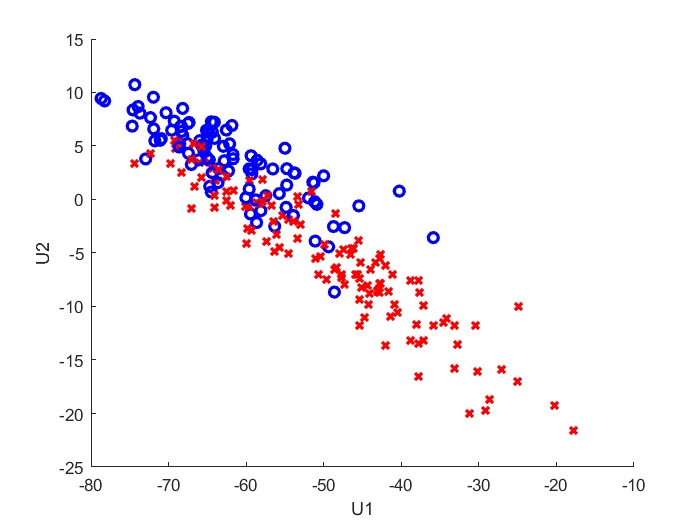

[U,S,V] = svd(obs);
figure, hold on;
for k=1:size(obs,2)
    x = transpose(obs(:,k))*U(:,1);
    y = transpose(obs(:,k))*U(:,2);
    z = transpose(obs(:,k))*U(:,3);
    
    if grp{k} == 'Cancer'
        plot3(x,y,z,'rx','LineWidth',2);
    else
        plot3(x,y,z,'bo','LineWidth',2);
    end
end
xlabel('U1');
ylabel('U2');
zlabel('U3');

% U1, U2 and U3 can be utilized along with machine learning techniques to
% carry out classification of ovarian cancer. This method is really helpful
% when the datat dimension is large. Here initially we had 4000 features
% however we see that with SVD we rduced it to only 3 features and still
% managed to get a plot where the datapoints are separable.